## **Part 1: Digital synthesis of arbitrary waveforms with specified SNR**

### Background

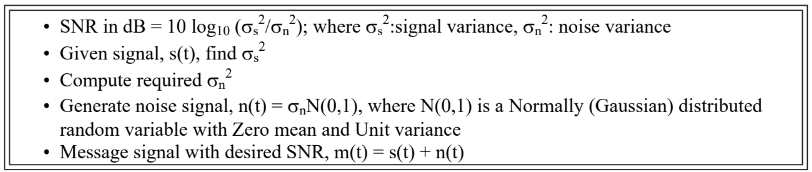

Procedure Overview

• Synthesize a 1 second A-Sharp sinusoidal tone (466.16 Hz) sampled at 8 kHz.

• Plot this waveform; observe and listen using the sound command in Matlab.

• Corrupt this signal with a Gaussian noise source to get an SNR of 10 dB. Observe, listen and save waveform as before.

• Synthesize 1 cycle of the noisy waveform.

• Vary the frequency, amplitude.

    Repeat experiment with various SNRs.

• Experiment with other waveforms:

Example Matlab Code

clear all
close all
hold off
%ECOMMS Lab Project 1 Example
%S. Mandayam, Rowan University
%This program generates a 1-second duration
%Asharp signal (466.16 Hz) with a specified SNR
%Specify SNR
snr=10;
%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5*sin(2*pi*466.16*t);
sound(s);
pause(2);

%Compute signal variance
var_s = cov(s);
%Calculate required noise variance
var_noise=var_s/(10^(snr/10));
%Generate noise
n=sqrt(var_noise)*randn(length(s),1);
sound(n);
pause(2);

%Add signal to noise and generate message
m=s+n;
sound(m);

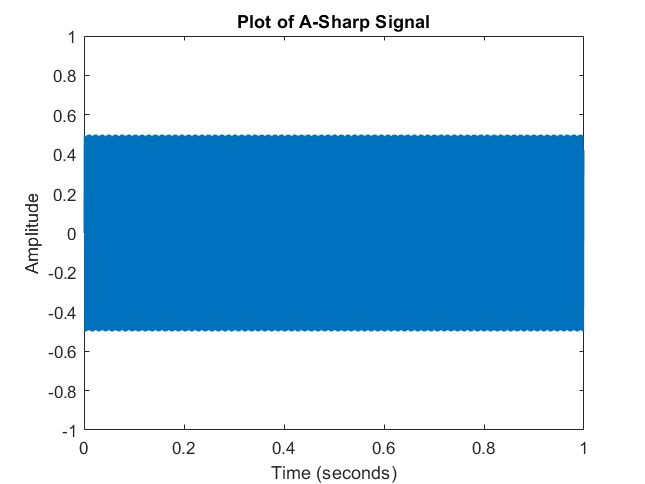

%Specify SNR
snr=10;
%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5*sin(2*pi*466.16*t);
sound(s);
plot(t, s)
pause(2);
title("Plot of A-Sharp Signal")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])

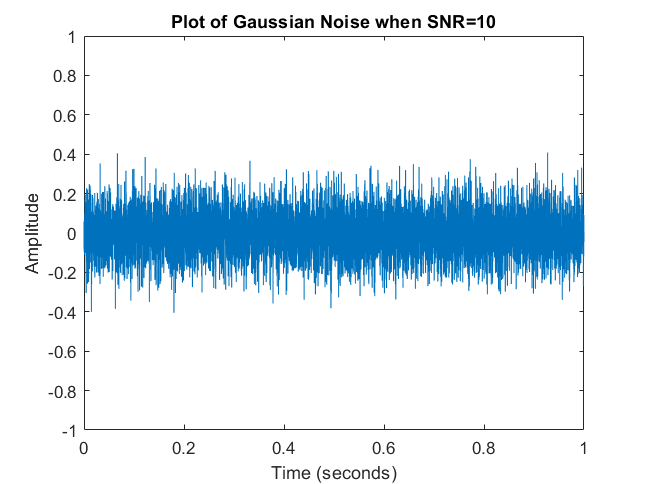


%Compute signal variance
var_s = cov(s);
%Calculate required noise variance
var_noise=var_s/(10^(snr/10));
%Generate noise
n=sqrt(var_noise)*randn(length(s),1);
sound(n);
plot (t, n)
title("Plot of Gaussian Noise when SNR=10")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])
pause(2);

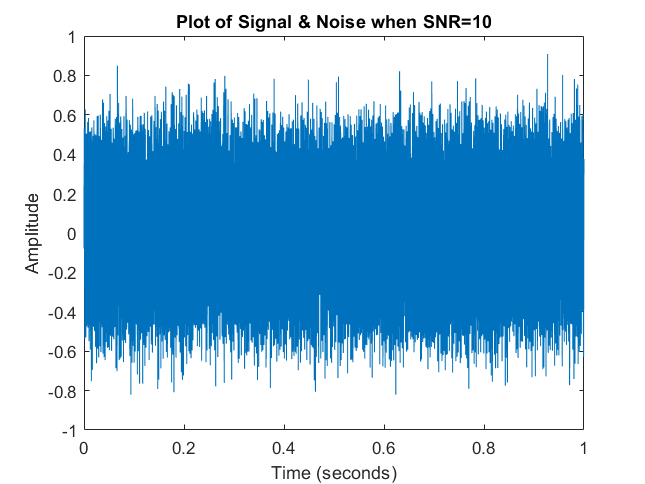


%Add signal to noise and generate message
m=s+n;
sound(m);
plot(t, m)
title("Plot of Signal & Noise when SNR=10")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])



%Specify SNR
snr=20;
%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5*sin(2*pi*466.16*t);
sound(s);
pause(2);

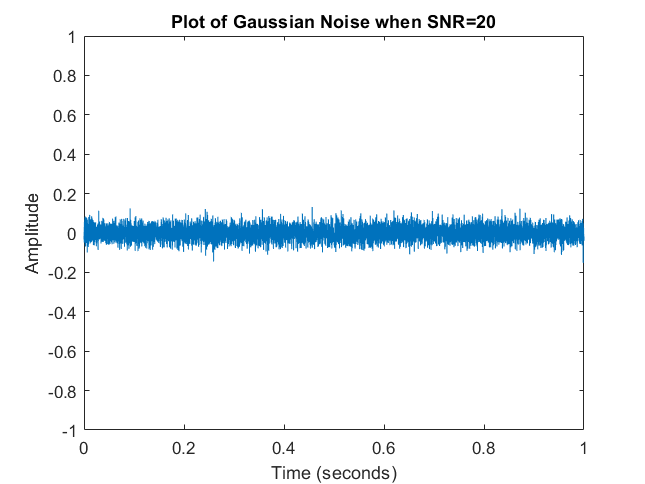


%Compute signal variance
var_s = cov(s);
%Calculate required noise variance
var_noise=var_s/(10^(snr/10));
%Generate noise
n=sqrt(var_noise)*randn(length(s),1);
sound(n);
plot (t, n)
title("Plot of Gaussian Noise when SNR=20")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])
pause(2);

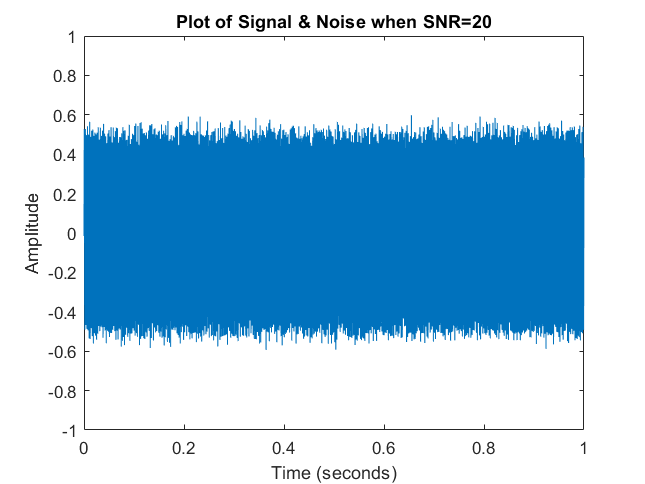


%Add signal to noise and generate message
m=s+n;
sound(m);
plot(t, m)
title("Plot of Signal & Noise when SNR=20")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])



%Specify SNR
snr=30;
%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5*sin(2*pi*466.16*t);
sound(s);
pause(2);

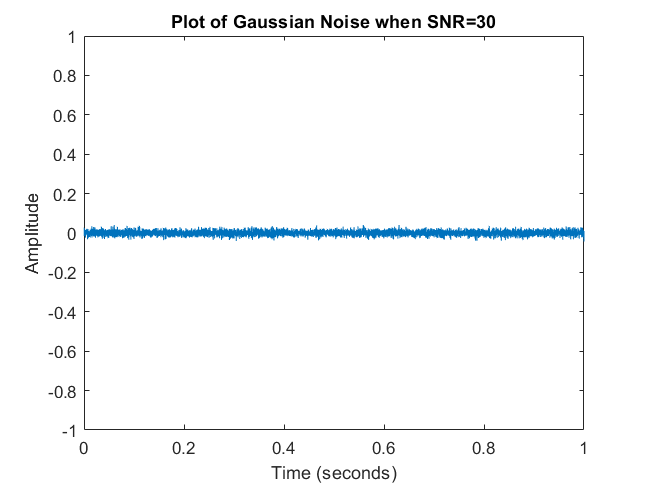


%Compute signal variance
var_s = cov(s);
%Calculate required noise variance
var_noise=var_s/(10^(snr/10));
%Generate noise
n=sqrt(var_noise)*randn(length(s),1);
sound(n);
plot (t, n)
title("Plot of Gaussian Noise when SNR=30")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])
pause(2);

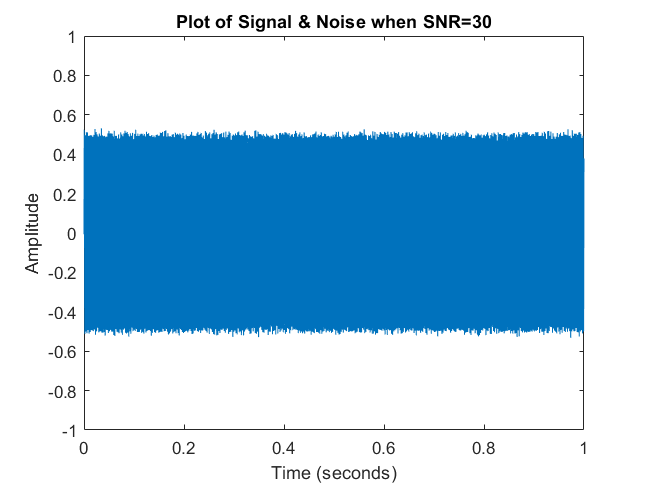


%Add signal to noise and generate message
m=s+n;
sound(m);
plot(t, m)
title("Plot of Signal & Noise when SNR=30")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])

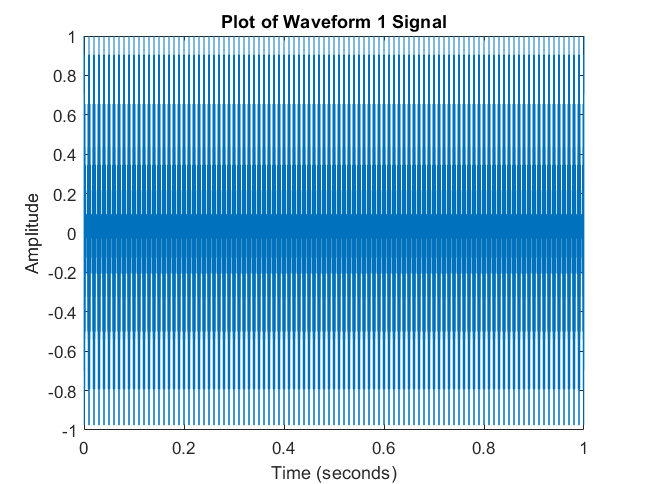




%Specify SNR
snr=10;
%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5.*(1+cos(2*pi*100*t)).*cos(2*pi*1000*t);
sound(s);
plot(t, s)
pause(2);
title("Plot of Waveform 1 Signal")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])

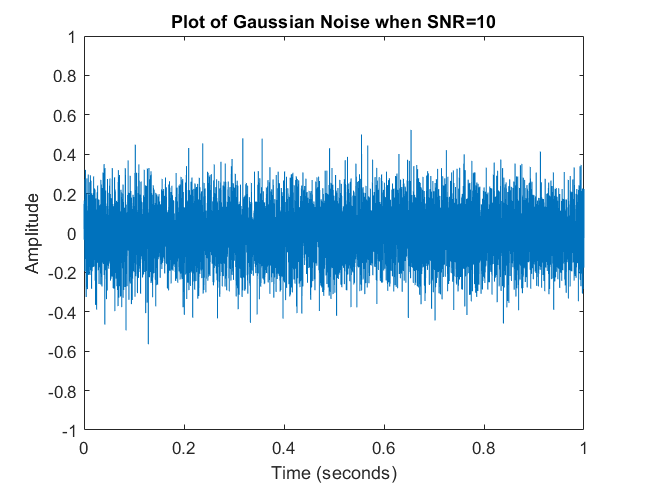


%Compute signal variance
var_s = cov(s);
%Calculate required noise variance
var_noise=var_s/(10^(snr/10));
%Generate noise
n=sqrt(var_noise)*randn(length(s),1);
sound(n);
plot (t, n)
title("Plot of Gaussian Noise when SNR=10")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])
pause(2);

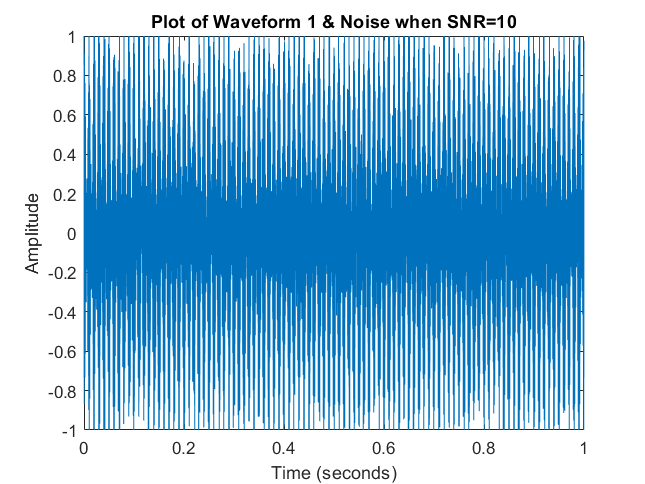


%Add signal to noise and generate message
m=s+n;
sound(m);
plot(t, m)
title("Plot of Waveform 1 & Noise when SNR=10")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])

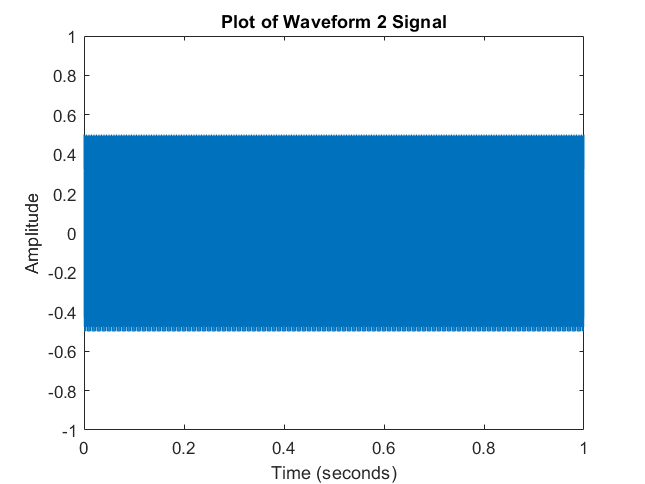




%Specify SNR
snr=10;
%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5*cos(2*pi*1000*t+sin(2*pi*100*t));
sound(s);
plot(t, s)
pause(2);
title("Plot of Waveform 2 Signal")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])

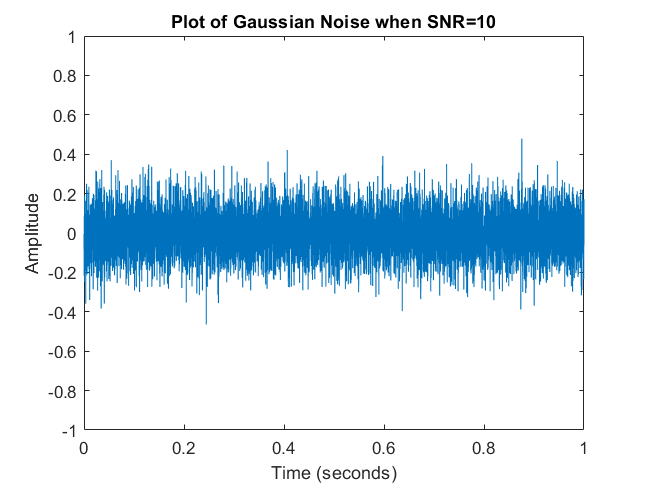


%Compute signal variance
var_s = cov(s);
%Calculate required noise variance
var_noise=var_s/(10^(snr/10));
%Generate noise
n=sqrt(var_noise)*randn(length(s),1);
sound(n);
plot (t, n)
title("Plot of Gaussian Noise when SNR=10")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])
pause(2);

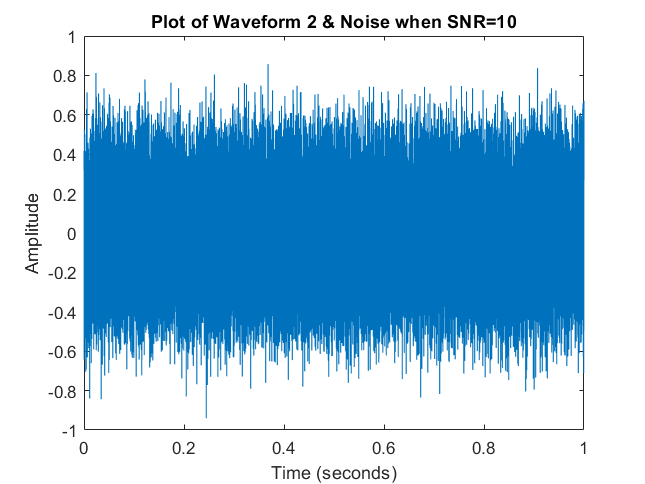


%Add signal to noise and generate message
m=s+n;
sound(m);
plot(t, m)
title("Plot of Waveform 2 & Noise when SNR=10")
xlabel("Time (seconds)")
ylabel("Amplitude")
ylim([-1 1])

## Part 2: Comparison between CFT and DFT (FFT)

Consider the signal shown in Figure 1:

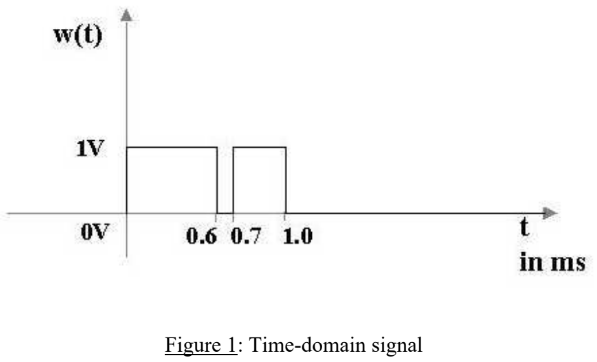

- Model the signal as a continuous-time function and plot.

- Obtain, **analytically**, the CFT of the signal, and plot.

- Based on your observations of the frequency components of the signal, determine the maximum sampling period/minimum sampling frequency that will allow reconstruction of the continuous-time signal.

- Plot the DFT magnitude spectrum using Matlab's fft function.

- Attempt to reconstruct the original continuous-time function from its samples, either by:

            ◦ Convolving the time domain samples with appropriate Sinc function (difficult), or

            ◦ Windowing the Fourier transform and taking the inverse Fourier transform (easier).

            Comment on your results.

- What is the maximum sampling period/minimum sampling frequency that will allow reconstruction of the discrete-time signal from its DFT, which adequately represents the original continuous-time signal? Show plots of the discrete-time signals, the corresponding DFTs and reconstructions, for sampling intervals at, above and below this maximum allowed sampling period.

clear all;
close all;
hold off;
syms t
x = rectangularPulse(0,0.6,t)+rectangularPulse(0.7,1,t);
%x = heaviside(t)-heaviside(t-0.6)+heaviside(t-0.7)-heaviside(t-1);
fplot(x)
grid on;
ylabel('w(t) [amplitude in volts]')
xlabel('t in ms')
axis([-0.5 1.5 -0.5 1.5])
title('Continuous-Time Function')

% Parameters for the signal
A1 = 1; % Amplitude of the first pulse
T1 = 0.6; % Width of the first pulse in seconds
t1_center = 0.3; % Center of the first pulse in seconds

A2 = 1; % Amplitude of the second pulse
T2 = 0.3; % Width of the second pulse in seconds
t2_center = 0.85; % Center of the second pulse in seconds

% Frequency vector for CTFT plot
f = linspace(-100, 100, 1000); % Frequency range from -100 to 100 Hz

% CTFT of the first pulse
X1 = A1 * T1 * sinc(T1 * f) .* exp(-1j * 2 * pi * f * t1_center);

% CTFT of the second pulse
X2 = A2 * T2 * sinc(T2 * f) .* exp(-1j * 2 * pi * f * t2_center);

% Total CTFT of the signal
X_total = X1 + X2;

% Plot the magnitude spectrum of the total CTFT
figure;
plot(f, abs(X_total), 'LineWidth', 1.5);
title('Magnitude Spectrum of the CTFT');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
grid on;

% Plot the phase spectrum of the total CTFT
figure;
plot(f, angle(X_total), 'LineWidth', 1.5);
title('Phase Spectrum of the CTFT');
xlabel('Frequency (Hz)');
ylabel('Phase of X(f)');
grid on;



% Define the time vector
fs = 1000; % Sampling frequency in Hz (for numerical approximation)
t = linspace(0, 1, fs); % Time vector from 0 to 1 second

% Define the original signal using the Heaviside function
x = heaviside(t) - heaviside(t - 0.6) + heaviside(t - 0.7) - heaviside(t - 1);

% Compute the DFT using fft
n = length(x); % Number of samples
X_f = fft(x); % Compute the FFT

% Compute the frequency vector
f = (0:n-1)*(fs/n); % Frequency vector from 0 to fs

% Plot the magnitude spectrum
figure;
plot(f, abs(X_f), 'LineWidth', 1.5);
title('DFT Magnitude Spectrum using FFT');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
grid on;
xlim([0, fs/2]); % Show only the positive frequency components



% Define the time vector
fs = 2000; % Sampling frequency in Hz (for numerical approximation)
t = linspace(-0.5, 1.5, fs); % Time vector from 0 to 1 second

% Define the original signal using the Heaviside function
x = heaviside(t) - heaviside(t - 0.6) + heaviside(t - 0.7) - heaviside(t - 1);

% Compute the DFT using fft
n = length(x); % Number of samples
X_f = fft(x); % Compute the FFT

% Apply a windowing function (e.g., rectangular window)
% Keep only the significant frequencies (low-pass filter)
window_size = 100; % Adjust this value to control the number of significant components
X_f_windowed = X_f;
X_f_windowed(window_size+1:end-window_size) = 0; % Zero out high-frequency components

% Reconstruct the signal using inverse FFT
x_reconstructed = ifft(X_f_windowed, 'symmetric');

% Plot the original and reconstructed signals
figure;
plot(t, x, 'LineWidth', 1.5); hold on;
plot(t, x_reconstructed, '--', 'LineWidth', 1.5);
title('Original and Reconstructed Signal');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original Signal', 'Reconstructed Signal');
grid on;
axis([-0.5 1.5 -0.2 1.2])



% Define the original signal parameters
t_orig = linspace(0, 1, 1000); % High-resolution time vector for the original signal
x_orig = heaviside(t_orig) - heaviside(t_orig - 0.6) + heaviside(t_orig - 0.7) - heaviside(t_orig - 1);

% Define different sampling frequencies
fs_values = [10, 6, 4]; % Sampling frequencies: at Nyquist, below Nyquist, above Nyquist

% Loop over each sampling frequency
for i = 1:length(fs_values)
    fs = fs_values(i);
    Ts = 1 / fs; % Sampling period
    t_samples = 0:Ts:1; % Sampled time vector
    x_samples = heaviside(t_samples) - heaviside(t_samples - 0.6) + heaviside(t_samples - 0.7) - heaviside(t_samples - 1);
    
    % Compute DFT using fft
    n = length(x_samples);
    X_f = fft(x_samples); % Compute the FFT
    f = (0:n-1)*(fs/n); % Frequency vector for DFT
    
    % Apply windowing (low-pass filtering)
    window_size = floor(n/2); % Half the DFT size for filtering
    X_f_windowed = X_f;
    X_f_windowed(window_size+1:end-window_size) = 0; % Zero out high-frequency components
    
    % Reconstruct the signal using inverse FFT
    x_reconstructed = ifft(ifftshift(X_f_windowed), 'symmetric');
    t_reconstructed = linspace(0, 1, length(x_reconstructed)); % Reconstructed time vector
    
    % Plot original sampled and reconstructed signals
    figure;
    subplot(3,1,1);
    stem(t_samples, x_samples, 'filled');
    title(['Sampled Signal at f_s = ' num2str(fs) ' Hz']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;

    subplot(3,1,2);
    plot(f, abs(X_f), 'LineWidth', 1.5);
    title(['DFT Magnitude Spectrum at f_s = ' num2str(fs) ' Hz']);
    xlabel('Frequency (Hz)');
    ylabel('|X(f)|');
    grid on;
    
    subplot(3,1,3);
    plot(t_reconstructed, real(x_reconstructed), 'LineWidth', 1.5);
    title(['Reconstructed Signal at f_s = ' num2str(fs) ' Hz']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
end

## Part 3: Spectral Analysis of AM and FM Signals

• Synthesize a bandpass AM signal, s(t) = Ac[1 + Amcos(2pfmt)]cos(2pfct) where fm = 5 kHz and fc = 25 kHz.

• Obtain and plot the spectral components of this signal using Matlab's fft function.

• Add noise to the RF signal, observe the signal in the time and spectral domains.

• Experiment with various fms, fcs and SNRs.

• Synthesize a bandpass FM signal, s(t) = Accos[2pfct + bf Amsin(2pfmt)] wherebf = Frequency 

    Modulation Index (choose initially = 10).

• Repeat earlier experiments.

% Parameters
fs = 1e6; % Sampling frequency (1 MHz)
t = 0:1/fs:1e-3; % Time vector (1 ms duration)
Am = 1; % Modulating signal amplitude
Ac = 1; % Carrier signal amplitude
fm = 5e3; % Modulating frequency (5 kHz)
fc = 25e3; % Carrier frequency (25 kHz)

% AM Signal
s_am = Ac * (1 + Am * cos(2*pi*fm*t)) .* cos(2*pi*fc*t);

% Plotting the AM Signal
figure;
subplot(2,1,1);
plot(t(1:500), s_am(1:500)); % Plotting a portion of the signal
title('AM Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% FFT and Spectral Analysis
N = length(s_am); % Number of points in FFT
S_am = fft(s_am);
f = (-N/2:N/2-1)*(fs/N); % Frequency vector

subplot(2,1,2);
plot(f, abs(fftshift(S_am))/N);
title('Spectrum of AM Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([-50e3, 50e3]); % Limit frequency range for better visualization


SNR = 10; % Signal-to-Noise Ratio (in dB)
s_am_noisy = awgn(s_am, SNR, 'measured'); % Add white Gaussian noise

% Plotting Noisy Signal in Time Domain
figure;
subplot(2,1,1);
plot(t(1:500), s_am_noisy(1:500));
title('Noisy AM Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% FFT and Spectral Analysis of Noisy Signal
S_am_noisy = fft(s_am_noisy);

subplot(2,1,2);
plot(f, abs(fftshift(S_am_noisy))/N);
title('Spectrum of Noisy AM Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([-50e3, 50e3]);


bf = 10; % Frequency modulation index
s_fm = Ac * cos(2*pi*fc*t + bf * Am * sin(2*pi*fm*t));

% Plotting the FM Signal in Time Domain
figure;
subplot(2,1,1);
plot(t(1:500), s_fm(1:500));
title('FM Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% FFT and Spectral Analysis of FM Signal
S_fm = fft(s_fm);

subplot(2,1,2);
plot(f, abs(fftshift(S_fm))/N);
title('Spectrum of FM Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([-50e3, 50e3]);


s_fm_noisy = awgn(s_fm, SNR, 'measured'); % Add noise to FM signal

% Plotting Noisy FM Signal in Time Domain
figure;
subplot(2,1,1);
plot(t(1:500), s_fm_noisy(1:500));
title('Noisy FM Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% FFT and Spectral Analysis of Noisy FM Signal
S_fm_noisy = fft(s_fm_noisy);

subplot(2,1,2);
plot(f, abs(fftshift(S_fm_noisy))/N);
title('Spectrum of Noisy FM Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([-50e3, 50e3]);

## Part 4: Spectral Analysis of Music Signal

Legally, download a segment of your favorite piece of music, import into Matlab and listen. Compute its spectrum in Matlab, observe.

clear all
hold off
% Read the audio file
[audioData, fs] = audioread('amish_paradise.mp3');  % Replace 'music.wav' with your file name

% Play the audio
sound(audioData, fs);

% Plot audio signal in time domain
t = (0:length(audioData)-1) / fs;  % Time vector
figure;
subplot(2, 1, 1);
plot(t, audioData);
title('Audio Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 210]);

% Compute the FFT of the audio signal
N = length(audioData);  % Number of samples
audioFFT = fft(audioData);  % Compute FFT
f = (-N/2:N/2-1)*(fs/N);  % Frequency vector

% Plot spectrum (magnitude of FFT)
subplot(2, 1, 2);
plot(f, abs(fftshift(audioFFT)) / N);
title('Spectrum of Audio Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([-fs/20, fs/20]);  % Show only positive frequencies
hold off